# COVID-19 Detection Using X-Rays

by Joshua Rothe

## Image pre-processing, K-Means

K = 3;  % for K-means

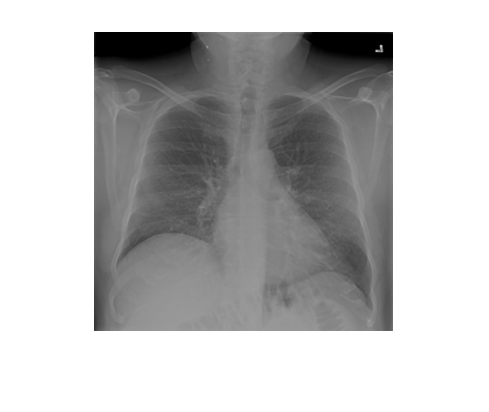

% Class - normal images
num_images = 2000;
normal_img = zeros((299*299),num_images);   % Initialize empty array
for i = 1:num_images
    filename = sprintf('./data/normal/Normal-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    normal_img(:,i) = double(reshape(img,[],1));    % reshapes image as column vector
end                                                 % and adds it to normal_img
labels(1:num_images,1) = "normal";
imshow(img);

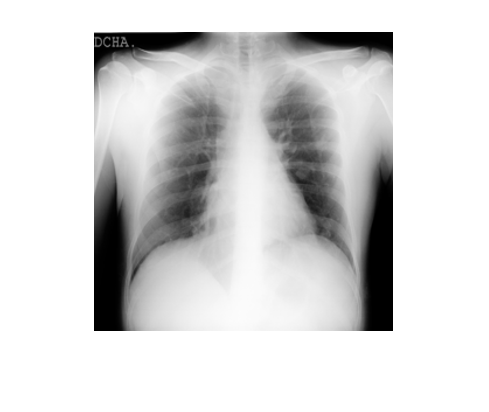

% Class - COVID
num_images2 = 1000;
cov_img = zeros((299*299),num_images2);  % Initialize empty array
for i = 1:num_images2
    filename = sprintf('./data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    cov_img(:,i) = double(reshape(img,[],1));       % reshapes image as column vector
end                                                 % and adds it to cov_img
labels(num_images+1:num_images2+num_images,1) = "COVID";
imshow(img);

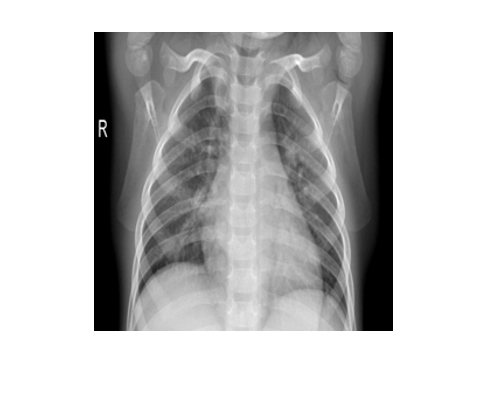

% Class - Viral Pneumonia images
num_images3 = 1000;
pnu_img = zeros((299*299),num_images3);   % Initialize empty array
for i = 1:num_images3
    filename = sprintf('./data/Viral Pneumonia/Viral Pneumonia-%i.png', i);
    img = (imread(filename));
    % Perform K-means for the image (comment out below if not using)
    % img = imsegkmeans(img,K);
    pnu_img(:,i) = double(reshape(img,[],1));   % reshapes image as column vector
end                                             % and adds it to pnu_img
labels(num_images+num_images2+1:num_images+num_images2+num_images3,1) = "viral pneumonia";                  
imshow(img);

% Combine images and labels
train_images = [normal_img, cov_img, pnu_img];
train_labels = labels;

## Apply PCA

%% Train and find the PCA dimensions of the training data
% First reduce the training data to a computationally manageable size
% (note: in this instance, size is unchanged, but may adjust as needed)
train_size = num_images + num_images2 + num_images3;
base = 50;         % Base size, given
% Reduced variables are for if we reduce the number if pics taken from
% dataset.
train_images_reduced = train_images(:,[1:train_size]);
train_labels_reduced = train_labels([1:train_size],:);
% Normalize the data, will be calling it X for simplicity
X = train_images_reduced;
Xmean = mean(X);    % mean of X
Xnorm = X - Xmean;  % normalized
% Calculate covariance matrix
covar_matrix = (Xnorm' * Xnorm) / (train_size - 1);
% Calculate Eigenvectors and Eigenvalues of Covariance Matrix
[Xeivec, Xeival] = eig(covar_matrix);
% Now project the dataset
proj_train = Xnorm * Xeivec;
% Back into larger data format
Xnormk_train = proj_train * Xeivec';

## Optimize Models

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.52825 |      686.34 |     0.52825 |     0.52825 |     onevsone |       69.893 |    0.0059595 |


|    2 | Accept |       0.563 |      566.81 |     0.52825 |      0.5306 |     onevsone |     0.025313 |      0.53863 |


|    3 | Best   |      0.5055 |      1127.9 |      0.5055 |      0.5055 |     onevsall |       63.698 |     0.017584 |


|    4 | Best   |     0.13125 |      1888.7 |     0.13125 |     0.13129 |     onevsall |       230.05 |       566.18 |


|    5 | Accept |      0.1315 |      1836.6 |     0.13125 |     0.13124 |     onevsall |    0.0089425 |       75.883 |


|    6 | Accept |     0.13125 |      1954.7 |     0.13125 |     0.13012 |     onevsall |      0.86278 |       204.84 |


|    7 | Accept |     0.14225 |      1969.3 |     0.13125 |     0.12873 |     onevsall |     0.004623 |       996.92 |


|    8 | Accept |     0.13125 |      1813.3 |     0.13125 |     0.13062 |     onevsall |      0.71297 |        193.9 |


|    9 | Accept |     0.13125 |      1771.9 |     0.13125 |     0.13056 |     onevsall |       997.65 |       86.083 |


|   10 | Accept |      0.1315 |      2185.4 |     0.13125 |     0.13083 |     onevsall |       11.028 |       14.389 |


|   11 | Accept |     0.13125 |      1770.6 |     0.13125 |     0.13068 |     onevsall |    0.0027714 |       28.556 |


|   12 | Accept |     0.13125 |      1772.2 |     0.13125 |     0.13093 |     onevsall |      0.43896 |       326.35 |


|   13 | Accept |     0.13125 |      1825.5 |     0.13125 |     0.13061 |     onevsall |       847.54 |       28.161 |


|   14 | Best   |     0.12125 |      773.84 |     0.12125 |     0.12128 |     onevsone |       290.69 |       996.64 |


|   15 | Accept |     0.12125 |      760.49 |     0.12125 |     0.12119 |     onevsone |        9.845 |       375.17 |


|   16 | Accept |     0.13175 |      753.23 |     0.12125 |     0.12143 |     onevsone |    0.0033518 |       605.67 |


|   17 | Accept |     0.12125 |       764.5 |     0.12125 |     0.12069 |     onevsone |       898.15 |       525.79 |


|   18 | Accept |     0.12125 |      761.38 |     0.12125 |     0.12071 |     onevsone |       994.66 |       139.87 |


|   19 | Accept |     0.12125 |      768.28 |     0.12125 |     0.11968 |     onevsone |       926.21 |       248.44 |


|   20 | Accept |     0.12125 |      762.43 |     0.12125 |     0.12026 |     onevsone |       993.06 |       261.13 |


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|   21 | Accept |     0.12125 |       760.6 |     0.12125 |     0.12056 |     onevsone |       982.35 |       305.11 |


|   22 | Accept |     0.12125 |      762.97 |     0.12125 |     0.12056 |     onevsone |       980.87 |       993.15 |


|   23 | Accept |     0.12125 |      767.65 |     0.12125 |     0.12068 |     onevsone |       999.39 |       225.57 |


|   24 | Accept |     0.12125 |       764.8 |     0.12125 |     0.12076 |     onevsone |       949.46 |       367.91 |


|   25 | Accept |     0.13375 |      2672.6 |     0.12125 |     0.12075 |     onevsall |     0.001033 |       2.5858 |


|   26 | Accept |     0.12125 |      777.18 |     0.12125 |     0.12077 |     onevsone |       977.98 |       186.18 |


|   27 | Accept |     0.12125 |      816.06 |     0.12125 |     0.12082 |     onevsone |       983.02 |       381.84 |


|   28 | Accept |     0.12125 |       805.6 |     0.12125 |     0.12082 |     onevsone |       986.05 |       973.48 |


|   29 | Accept |      0.5055 |      1063.2 |     0.12125 |     0.12083 |     onevsall |    0.0011969 |    0.0010011 |


|   30 | Accept |     0.52825 |      660.05 |     0.12125 |     0.12083 |     onevsone |      0.11906 |    0.0010002 |


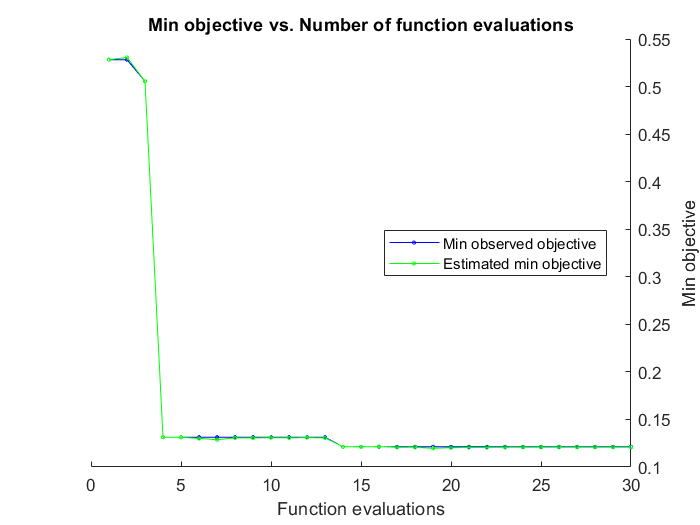


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 36407.5299 seconds.
Total objective function evaluation time: 36363.9918

Best observed feasible point:
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsone       290.69          996.64   

Observed objective function value = 0.12125
Estimated objective function value = 0.12194
Function evaluation time = 773.8404

Best estimated feasible point (according to models):
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsone       982.35          305.11   

Estimated objective function value = 0.12083
Estimated function e

Mdl_opt_pnu =   ClassificationECOC
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'COVID'  'normal'  'viral pneumonia'}
                       ScoreTransform: 'none'
                       BinaryLearners: {3×1 cell}
                           CodingName: 'onevsone'
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


% Find optimised numbers using MATLAB
Mdl_opt_pnu = fitcecoc(Xnormk_train',train_labels_reduced','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))